% m * ddz = b_m /z +b_s*i/z -mg
% ddz = [b_m /z +b_s*i/z]/m -g
dt = 0.001;

params

% Simulation
tic
% Initialize variables
prev_error = 0;
integral = 0;
prev_t = 0;
z0 = z_eq + 0.0;            % Initial condition
% Pre-allocate arrays to store results
tf = 5.0

tf = 5

Freq = 1 / dt;

tSpan = linspace(0,tf,tf*Freq); % Time vector of tf seconds (100Hz)
z_ref = @(t) z_eq + 0.01 * sin(2*pi*t);
dz_ref = @(t) 2*pi* 0.01 * cos(2*pi*t);
ddz_ref = @(t) -4*(pi^2)* 0.01 * sin(2*pi*t);
num_steps = tf * Freq;
t_result = zeros(num_steps, 1);
x_result = zeros(num_steps, 2);
u_signal = zeros(num_steps, 1);
error_sig = zeros(num_steps, 1);

%Gains
K = 1000000;
K_d = 10000;
K_i = 0;

% Control loop
t_current = 0.0;
x_current = zeros(2,1);
x_current(1) = z0;
for i = 1:num_steps
    % Calculate error
    error = z_ref(t_current) - x_current(1);
    error_sig(i) = error;

    % Calculate derivative of error
    derivative = dz_ref(t_current) - x_current(2);

    % Update integral term
    integral = integral + error * dt;
  
    % Calculate control signal
    u = - m * g /b_s + (m/b_s) * ddz_ref(t_current) + (b_m/(b_s * z0^2)) * z_ref(t_current);
    
    % transform
    u = x_current(1) * (u + K * error + K_i * integral / x_current(1) + K_d * derivative);
    u_signal(i) = u;

    % Store current time and state
    t_result(i) = t_current;
    x_result(i, :) = x_current;
    
    % Update state using ode45
    [t_out, x_out] = ode15s(@(t, x) f_sim(x, u), [t_current t_current + dt], x_current);
    
    % Update current time and state for next iteration
    prev_error = error;
    prev_t = t_current;
    t_current = t_out(end);
    x_current = x_out(end, :);
end


fprintf('simulation time: %.2fs\n', toc)

simulation time: 1.52s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

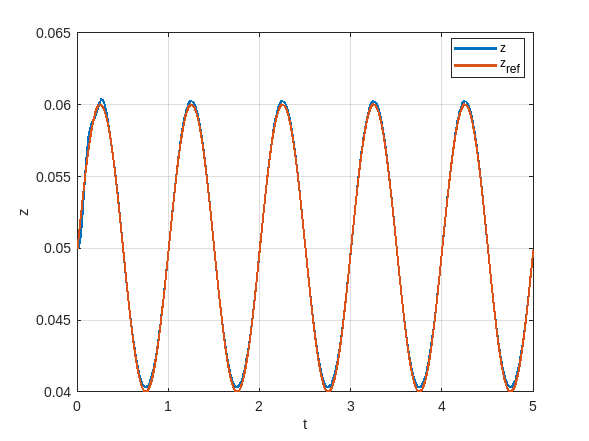

figure;
clf; grid on; hold on; box on;

plot(t_result, x_result(:, 1),'linewidth',2)
plot(t_result, z_ref(t_result),'linewidth',2)
legend({'z','z_{ref}'},'location','best')
xlabel('t')
ylabel('z')

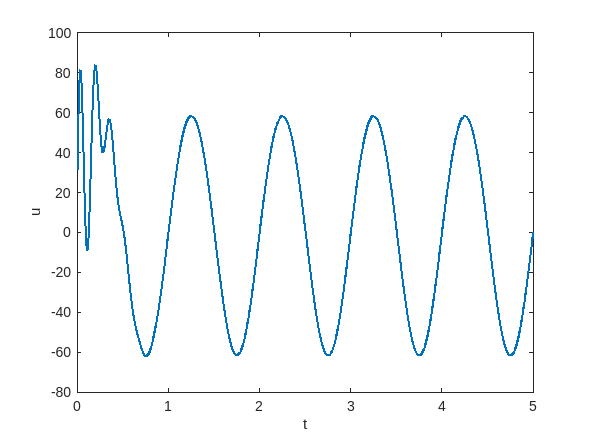

figure
plot(t_result, u_signal,'linewidth',2)
xlabel('t')
ylabel('u')